# Problem Set 2

## Problem 1

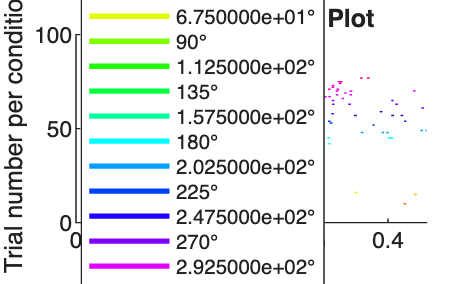

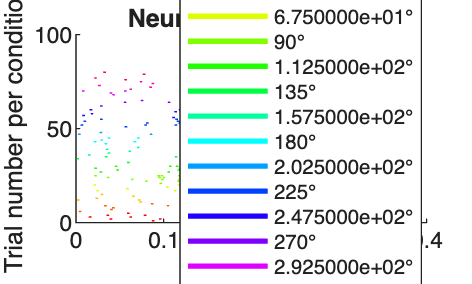

% Part A
neurons = length(Data.spikes);
mean_spikes = cell(1, neurons);

for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    for cond = 1:length(unique_conds)
        cond_mask = stimuli == unique_conds(cond);
        spikes_per_cond = spikes(cond_mask);
        counts = cellfun(@length, spikes_per_cond);
        mean_spikes{neuron}(cond) = mean(counts);
    end
end

% Part B
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    figure; hold on;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    colors = hsv(length(unique_conds)); 
    row = 1;
    
    for cond = 1:length(unique_conds)
        dir = unique_conds(cond);
        trial_idx = find(stimuli == dir);
        legend_handles(cond) = plot(nan, nan, 'Color', colors(cond,:), 'LineWidth', 2);
        for t = 1:length(trial_idx)
            trial_spikes = spikes{trial_idx(t)};
            for s = 1:length(trial_spikes)
                plot([trial_spikes(s) trial_spikes(s)], [row-0.4 row+0.4], 'Color', colors(cond,:), 'LineWidth', 1);
            end
            row = row + 1;
        end
    end
    xlabel('Time (s)');
    ylabel('Trial number per condition');
    title(['Neuron ' num2str(neuron) ' Raster Plot']);
    
    legend_labels = arrayfun(@(cond) sprintf('%d°', cond), unique_conds, 'UniformOutput', false);
    legend(legend_handles, legend_labels, 'Location', 'best');
end

Neuron 1 seems to respond mostly to one range of angle directions (210-340 ish). while Neuron 2 preferentially responds to two different angles (210-340 ish and 25-150 ish). 

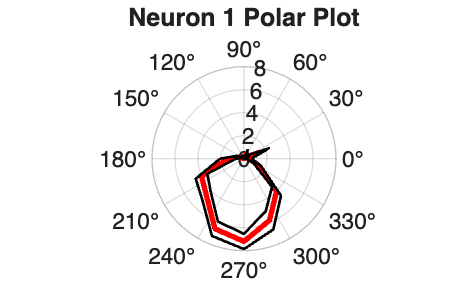

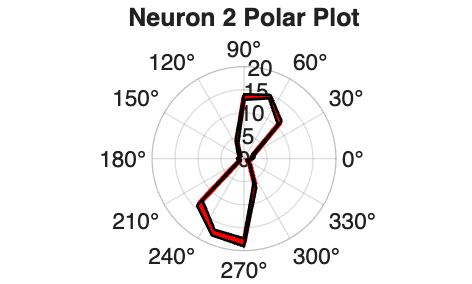

% Part C
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    
    mean_rates = zeros(size(unique_conds));
    sem_rates = zeros(size(unique_conds));
    
    for cond = 1:length(unique_conds)
        dir = unique_conds(cond);
        trial_idx = find(stimuli == dir);
        spike_counts = cellfun(@length, spikes(trial_idx));
        mean_rates(cond) = mean(spike_counts);
        sem_rates(cond) = std(spike_counts) / sqrt(length(spike_counts));
    end
    
    theta = deg2rad(unique_conds);
    theta_closed = [theta; theta(1)];
    mean_closed = [mean_rates; mean_rates(1)];
    sem_closed = [sem_rates; sem_rates(1)];

    upper = mean_rates + sem_rates;
    lower = mean_rates - sem_rates;
    upper_closed = [upper; upper(1)];
    lower_closed = [lower; lower(1)];
    
    figure;
    polarplot(theta_closed, mean_closed, 'r-', 'LineWidth', 2);
    hold on;
    polarplot(theta_closed, upper_closed, 'k-', 'LineWidth', 1);
    polarplot(theta_closed, lower_closed, 'k-', 'LineWidth', 1);
    
    title(['Neuron ' num2str(neuron) ' Polar Plot']);
end

Neuron 1 seems preferentially tuned to one range of angle directions (210-320 ish), while Neuron 2 seems tuned to two different direction ranges (220-270 ish and 40-90 ish). Neuron 2 has a stronger response to its preferred angles and is less variable than neuron 1 as shown through the error lines. 

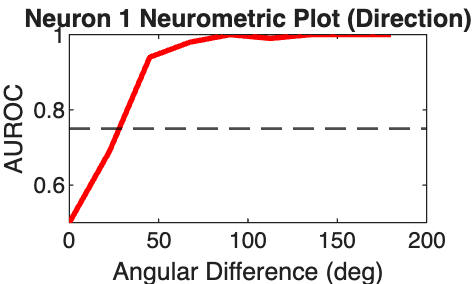

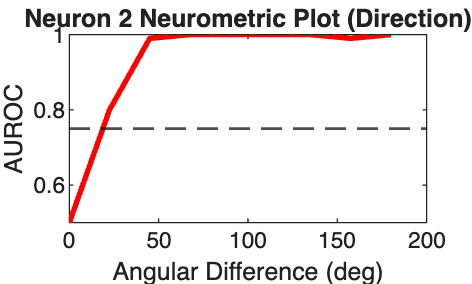

% Part D
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    stimuli = Data.stimuli{1, neuron}(trial_mask, 3);
    unique_conds = unique(stimuli);
    
    mean_rates = zeros(size(unique_conds));
    
    for cond = 1:length(unique_conds)
        idx = stimuli == unique_conds(cond);
        mean_rates(cond) = mean(cellfun(@length, spikes(idx)));
    end
    
    [~, pref_idx] = max(mean_rates);
    pref_dir = unique_conds(pref_idx);
    
    auroc_vals = [];
    angle_diffs = [];
    
    pref_counts = cellfun(@length, spikes(stimuli == pref_dir));
    
    for cond = 1:length(unique_conds)
        
        test_dir = unique_conds(cond);
        test_counts = cellfun(@length, spikes(stimuli == test_dir));
        
        labels = [ones(length(pref_counts),1); zeros(length(test_counts),1)];
        scores = [pref_counts; test_counts];
        
        [~,~,~,AUC] = perfcurve(labels, scores, 1);
        
        diff = abs(pref_dir - test_dir);
        diff = min(diff, 360 - diff);
        
        auroc_vals(end+1) = AUC;
        angle_diffs(end+1) = diff;
    end

    [unique_diffs, ~, idx_groups] = unique(angle_diffs);
    mean_auroc = accumarray(idx_groups, auroc_vals, [], @mean);

    [unique_diffs, sort_idx] = sort(unique_diffs);
    mean_auroc = mean_auroc(sort_idx);

    figure;
    plot(unique_diffs, mean_auroc, 'r-', 'LineWidth', 2);
    hold on;
    yline(0.75, 'k--', 'LineWidth', 1);
    
    xlabel('Angular Difference (deg)');
    ylabel('AUROC');
    title(['Neuron ' num2str(neuron) ' Neurometric Plot (Direction)']);   
    ylim([0.5 1]);
end

The threshold for Neuron 1 is approximately 25 degrees and the threshold for Neuron 2 is approximately 15 degrees according to my plots. 

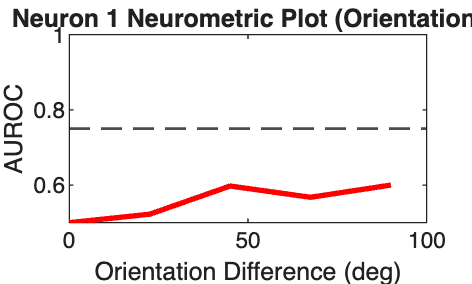

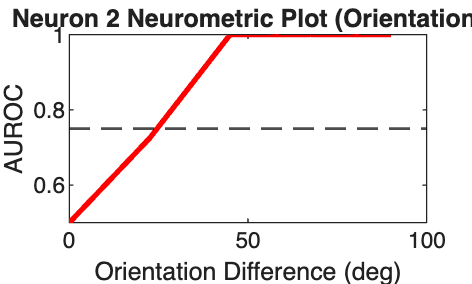

% Part E
for neuron = 1:neurons
    trial_mask = Data.stimuli{1, neuron}(:, 2) == 700;
    spikes = Data.spikes{1, neuron}(trial_mask);
    directions = Data.stimuli{1, neuron}(trial_mask, 3);
    
    orientations = mod(directions + 90, 180);
    unique_conds = unique(orientations);
    mean_rates = zeros(size(unique_conds));
    
    for cond = 1:length(unique_conds)
        idx = orientations == unique_conds(cond);
        mean_rates(cond) = mean(cellfun(@length, spikes(idx)));
    end
    
    [~, pref_idx] = max(mean_rates);
    pref_ori = unique_conds(pref_idx);
    
    pref_counts = cellfun(@length, spikes(orientations == pref_ori));
    
    auroc_vals = [];
    ori_diffs = [];
    
    for cond = 1:length(unique_conds)
        
        test_ori = unique_conds(cond);
        test_counts = cellfun(@length, spikes(orientations == test_ori));
        
        labels = [ones(length(pref_counts),1); zeros(length(test_counts),1)];
        scores = [pref_counts; test_counts];
        
        [~,~,~,AUC] = perfcurve(labels, scores, 1);
        
        diff = abs(pref_ori - test_ori);
        diff = min(diff, 180 - diff);
        
        auroc_vals(end+1) = AUC;
        ori_diffs(end+1) = diff;
    end
    [unique_diffs, ~, idx_groups] = unique(ori_diffs);
    mean_auroc = accumarray(idx_groups, auroc_vals, [], @mean);

    [unique_diffs, sort_idx] = sort(unique_diffs);
    mean_auroc = mean_auroc(sort_idx);
    
    figure;
    plot(unique_diffs, mean_auroc, 'r-', 'LineWidth', 2);
    hold on;
    yline(0.75, 'k--', 'LineWidth', 1);
    
    xlabel('Orientation Difference (deg)');
    ylabel('AUROC');
    title(['Neuron ' num2str(neuron) ' Neurometric Plot (Orientation)']);
    ylim([0.5 1]);

end

Neuron 1 does not cross the threshold, and Neuron 2, the approximate threshold is 25 degrees. Neuron 1 is tuned to angles in the range of 210 to 310 and shows a weaker response than Neuron 2. There is also a response at around 25 degrees as well. Neuron 2 is strongly tuned to two angle ranges 45 to 90 and 220 to 300. Neuron 1 is tuned to direction and not orientation as evidenced by the neurometric plots. Neuron 2 is tuned to direction and orientation by the same metric. 

## 2.1 Visualization: scatter plots

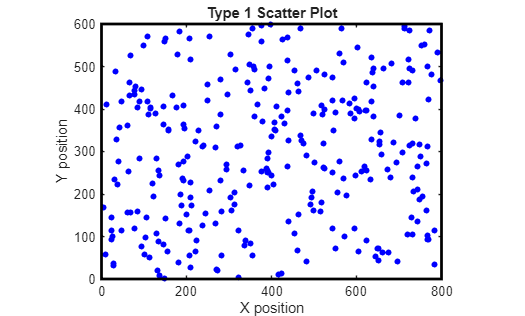

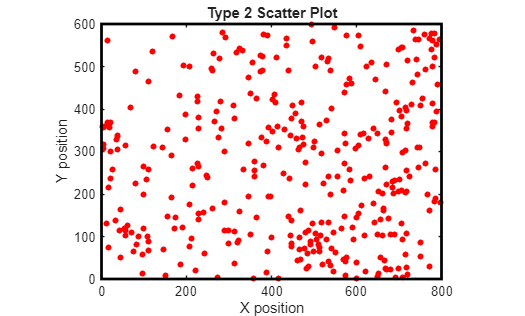

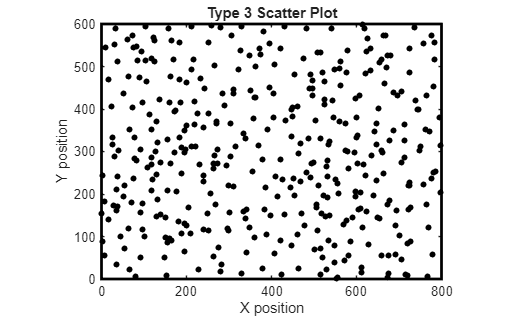

% Part A
colors = {'b', 'r', 'k'};
titles = {'Type 1', 'Type 2', 'Type 3'};

for neuron = 1:3
    figure;
    location = data(neuron).locsXY;
    
    plot(location(:,1), location(:,2), 'o', ...
        'MarkerEdgeColor', colors{neuron}, ...
        'MarkerFaceColor', colors{neuron}, ...
        'MarkerSize', 4);
    hold on;
    
    fov = data(neuron).fovSizeXY;
    rectangle('Position', [0, 0, fov(1), fov(2)], ...
              'EdgeColor', 'k', 'LineWidth', 2);
    
    axis equal;
    xlim([0 fov(1)]);
    ylim([0 fov(2)]);
    
    xlabel('X position');
    ylabel('Y position');
    title([titles{neuron} ' Scatter Plot']);
end

## 2.2 Nearest-Neighbor Plots

% Part A
function nnDist = nearestNeighborDistances(locsXY)
    D = pdist2(locsXY, locsXY);
    D(1:size(D,1)+1:end) = inf;
    nnDist = min(D, [], 2);
end
nnDists = cell(1,3);
medians = zeros(1,3);

% Part B
for i = 1:3
    locs = data(i).locsXY;
    nnDists{i} = nearestNeighborDistances(locs);
    medians(i) = median(nnDists{i});
end
allDists = vertcat(nnDists{:});
colors = {'b','r','k'};

for i = 1:3
    figure;
    
    histogram(nnDists{i}, 'BinWidth', 5, 'FaceColor', colors{i});
    hold on;
    plot(medians(i), 0, 'rx', 'MarkerSize', 12, 'LineWidth', 2);
    xlabel('Nearest Neighbor Distance');
    ylabel('Count');
    title(['Neuron Type ' num2str(i) ' Histogram']);
    xlim([edges(1) edges(end)]);
end

for i = 1:3
    locs = data(i).locsXY;
    D = pdist2(locs, locs);
    D(1:size(D,1)+1:end) = inf;
    [~, nnIdx] = min(D, [], 2);

    figure;
    hold on;
    plot(locs(:,1), locs(:,2), 'o', ...
        'MarkerFaceColor', colors{i}, ...
        'MarkerEdgeColor', colors{i});
    for j = 1:size(locs,1)
        x = [locs(j,1), locs(nnIdx(j),1)];
        y = [locs(j,2), locs(nnIdx(j),2)];
        
        plot(x, y, colors{i});
    end
    
    fov = data(i).fovSizeXY;
    rectangle('Position', [0 0 fov(1) fov(2)], 'EdgeColor', 'k');
    axis equal;
    xlim([0 fov(1)]);
    ylim([0 fov(2)]);
    title(['Neuron Type ' num2str(i) ' with Nearest Neighbors']);
end


## Part 2.3: Testing for Clustery-ness

% Part A
function locs = generateRandomLocs(n, fov)
    x = rand(n,1) * fov(1);
    y = rand(n,1) * fov(2);
    locs = [x y];
end

% Part B
numRuns = 1000;
mcMedians = zeros(numRuns,1);
locs_real = data(1).locsXY;
fov = data(1).fovSizeXY;
n = size(locs_real,1);

real_nn = nearestNeighborDistances(locs_real);
real_median = median(real_nn);

for i = 1:numRuns
    locs_rand = generateRandomLocs(n, fov);
    nn_rand = nearestNeighborDistances(locs_rand);
    mcMedians(i) = median(nn_rand);
end

% Part C
p_lower = mean(mcMedians <= real_median);
p_upper = mean(mcMedians >= real_median);
p_one_tailed = min(p_lower, p_upper);
p_two_tailed = 2 * p_one_tailed;
if real_median < mean(mcMedians)
    direction = 'more clustered';

Cell type 1 is more clustered than random, p = 0.476


else
    direction = 'less clustered';
end

% Part D
fprintf('Cell type 1 is %s than random, p = %.3f\n', ...
        direction, p_two_tailed);

% Repeat for all three neuron types (Part E?)
numRuns = 1000;

for neuron = 1:3
    
    locs_real = data(neuron).locsXY;
    fov = data(neuron).fovSizeXY;
    n = size(locs_real,1);
    
    real_nn = nearestNeighborDistances(locs_real);
    real_median = median(real_nn);
    
    mcMedians = zeros(numRuns,1);
    
    for i = 1:numRuns
        locs_rand = generateRandomLocs(n, fov);
        nn_rand = nearestNeighborDistances(locs_rand);
        mcMedians(i) = median(nn_rand);
    end
    
    p_lower = mean(mcMedians <= real_median);
    p_upper = mean(mcMedians >= real_median);
    
    p_two = 2 * min(p_lower, p_upper);
    
    if real_median < mean(mcMedians)
        direction = 'more clustered';

Cell type 1 is more clustered than random, p = 0.508
Cell type 2 is more clustered than random, p = 0.004
Cell type 3 is less clustered than random, p = 0.004


    else
        direction = 'less clustered';
    end
    
    fprintf('Cell type %d is %s than random, p = %.3f\n', ...
        neuron, direction, p_two);
end


- This is an example of sampling from the null.

- We should believe 2 decimal places because we used 1000 samples. We should select a p-value with one decimal place less than the order of magnitude of the number of samples. 

- We would use a shuffling procedure that we discussed in class. We would assume all cell types are composed of a heterogenous group and randomly split this group. If each random split has no significant difference between the groups, the differences we observed from originally separating the groups can be thought to be significant. We will repeat this procedure many times to increase our confidence in the significance of our result. 

## Problem 3: An Easy Bootstrap

% Part A
n = 100;
data = 2 * randn(n,1); 

SEM: 0.202



% Part B
sem = std(data) / sqrt(n);
fprintf('SEM: %.3f\n', sem);

% Part C
num_bootstrap = 1000;
boot_means = zeros(num_bootstrap,1);

for i = 1:num_bootstrap
    idx = randi(n, n, 1);
    sample = data(idx);
    boot_means(i) = mean(sample);
end

Bootstrap standard deviation: 0.203



% Part D
boot_std = std(boot_means);
fprintf('Bootstrap standard deviation: %.3f\n', boot_std);

The values of the SEM and the bootstrap standard deviation are very close (0.202 vs 0.203). With the SEM, we estimate the standard deviation of the sampling distribution of the mean with a formula (standard deviation divided by square root of number of the samples). When we bootstrap, we get a distribution of the means of our data by resampling the data repeatedly. Finding the standard deviation of this is the same process of calculating the SEM. Therefore, the values are very close because they both estimate the standard deviation of the sampling distribution of the mean. 